# Linearization: Nonlinear Water Tank

**Author**: Ing. Jan Hauser

## Differential Equation

The aim of this script is to introduce simple nonlinear system and explore linearization in operation point (e.g. equilibrium) and about trajectory. Let's simulate these features on nonlinear model of conical water tank. 

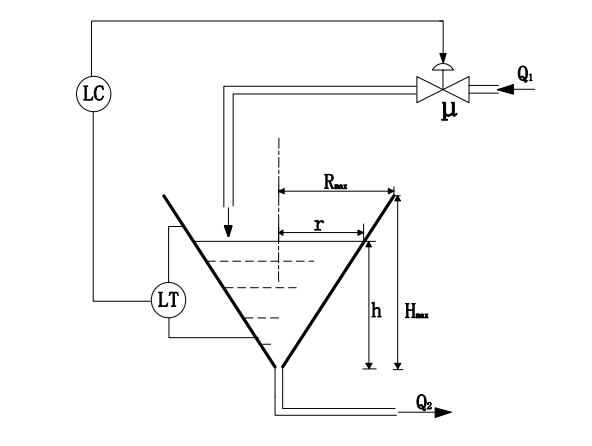

The conical tank is described by height $H_{\max }$ and maximal radius $R_{\max }$. 


$$Q_1 =K_{\mu } \mu$$
 

is an input constant volumetric flow of liquid with constant density, which is fed into the tank and controlled by the valve opening $\mu \;\left(0-100%\right)$ and the valve flow coefficinet $K_{\mu }$. 


$$Q_2 =K_{\nu } \sqrt{h}$$
 

is an output flow of the tank, where $K_{\nu }$ is the valve coefficient and $h$ is the actual height of the liquid in the tank. Finally, $r$ stands for the actual radius of the liquid. 

Such a system of first order is described by differential equation

$\dot{h} =\frac{H_{\max }^2 \left(K_{\mu } \mu -K_{\nu } \sqrt{h}\right)}{\pi R_{\max }^2 h^2 }$,

for derivation see (1). There is one input $\mu$ and one state/output $h$. Steady state solution for such a system is 

$\dot{h} =0$,

$K_{\mu } \mu =K_{\nu } \sqrt{h}$.

Using this solution, it is possible to find an operation point $\mu_p ,h_p$ (e.g. equilibrium). 

All the parameters are defined below in a short script. There is also definition of operation point and trajectory, both used for linearization (in operation point/about trajectory).

% Differential equation of Nonlinear Water Tank:
% 
% dh   hmax^2*(kmu*mu-kv*sqrt(h))
% -- = --------------------------
% dt         pi*rmax^2*h^2)

hmax = 5;               % ... height [m]
rmax = 2;               % ... maximal radius [m]
kv = 0.2;               % ... valve coefficient [m2.5/s]
kmu = 0.8;              % ... valve flow coefficient [m3/s]

% Steady state: 
% 
% dh
% -- = 0
% dt 
% 
%       kv*sqrt(hp)
% mup = -----------
%          kmu

hp = 0.2;               % ... initial height [m], try to change in interval (0-5>
mup = kv*sqrt(hp)/kmu;  % ... control valve opening coefficient [~]; steady state => equilibrium
% mup = 0.4;              % ... control valve opening coefficient [~]; custom operation point

disp(['Operation point [hp; mup]= [',num2str(hp),'; ',num2str(mup),']'])

Operation point [hp; mup]= [0.2; 0.1118]


disp('Trajectory [htilde; htildedot]= [1-exp(-t),;exp(-t)]')

Trajectory [htilde; htildedot]= [1-exp(-t),;exp(-t)]


## Linearization

Following script solves linearization in general operation point in Matlab for nonlinear water tank.

% Linearization

syms f(h,mu)
f(h,mu) = hmax^2*(kmu*mu-kv*sqrt(h))/(pi*rmax^2*h^2);

% Derivation according to x and u:
dh = diff(f,h);
dmu = diff(f,mu);

% Define linearized system in operation point:
A = double(dh(hp,mup));
B = double(dmu(hp,mup));
C = 1;
D = 0;
sys = ss(A,B,C,D);
figure(1);
step(sys);

Note that if linearized system is created either in operation point or about trajectory, then it is valid **only** close to this operation point or trajectory. Linearized model does **not** follow whole the nonlinear model state space. See plot below to understand how big the difference could be in some cases.

% Show region of validity 
mugrid = max(0.1, mup-0.1):0.01:min(1,mup+0.1);
hgrid = max(0.1, hp-0.1):0.01:min(5,hp+0.1);
[mu, h] = meshgrid(mugrid,hgrid);

ii = size(mugrid,2);
jj = size(hgrid,2);
hdotnl = double(f(h,mu));
hdotl = A*(h-hp)+B*(mu-mup);
op = double(f(hp, mup));

figure(2);
mesh(h,mu,hdotnl,'edgecolor','b');
hold on;
mesh(h,mu,hdotl,'edgecolor','r');
scatter3(hp,mup,op,'g');
xlabel('h');
ylabel('mu');
zlabel('dh/dt');
legend('Nonlinear Water Tank', 'Linearized Water Tank', 'Operation Point');
view([-33.1 8.4]);

Now please try the simulink model for different operation points. 

nonlinear_water_tank_model

Note: Always change $\textrm{h0}$ and $\textrm{mu0}$ here in this script in order to see change in simulink model.

## References:

(1) Xiangshun Li and Zhiang Li: The Application of Linear and Nonlinear Water Tanks Case Study in Teaching of Process Control; 2018 IOP Conf. Ser.: Earth Environ. Sci. 113 012165